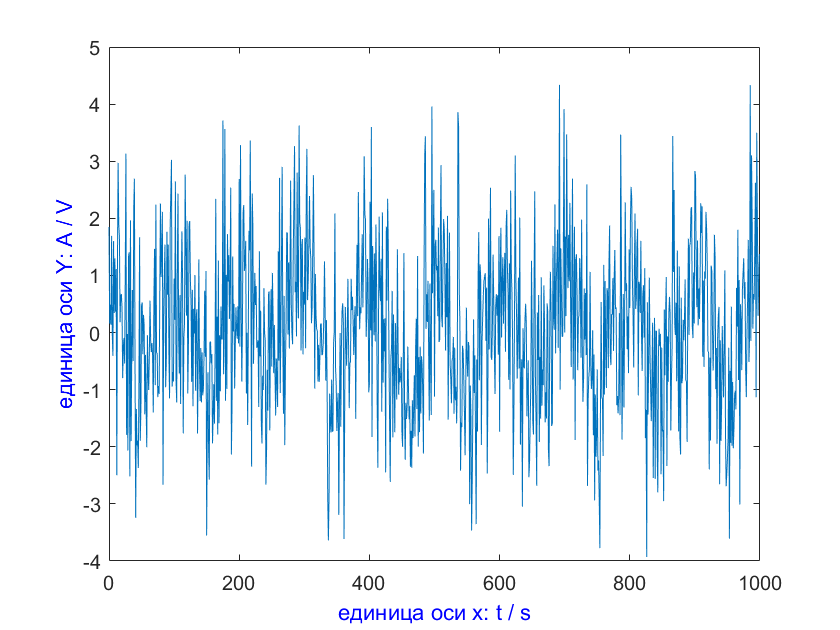

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear all; close all;  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% входной сигнал
 A = 1;% амплитуда сигнала
 f = 1000; %частота сигнала%
 fs = 10 ^ 5;% частота выборки
 t = (0: 999);% точка отбора проб
 Mlag = 100; %переменная длины связанной функции%   
 x = A * cos (2 * pi * f * t / fs);% входной синусоидальный сигнал
 xmean = mean(x);% среднее значение синусоидального сигнала
 xvar = var (x, 1);% дисперсии синусоидального сигнала
 noise = wgn (1,1000,2);% производит матрицу с 1 строкой и 1000 столбцами, а интенсивность составляет 2dbw
 xn = x + noise;% добавляет гауссовский белый шум с отношением сигнал / шум 20 дБ к синусоидальному сигналу
plot(t,xn)    
 xlabel ('единица оси x: t / s', 'color', 'b')
 ylabel ('единица оси Y: A / V', 'color', 'b')

 xnmean = mean(xn)% Рассчитать среднее значение шумового сигнала

xnmean = 0.0465

 xnms = mean(xn.^2)% Рассчитать среднеквадратичное значение шумового сигнала

xnms = 1.9966

 xnvar = var (xn, 1)% Рассчитать дисперсию входного сигнала

xnvar = 1.9944

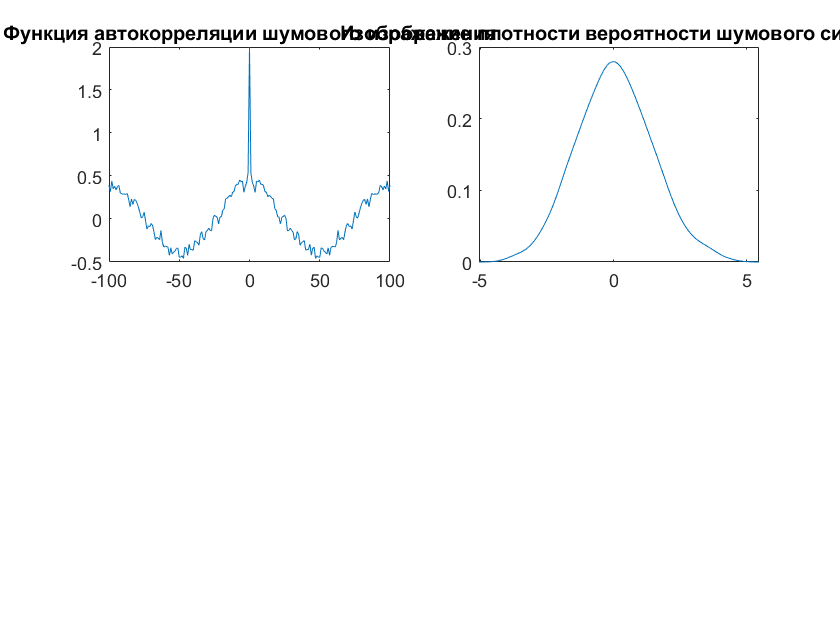

 Rxn = xcorr (xn, Mlag, 'biased');% Рассчитать функцию автокорреляции шумового сигнала
figure(2)
subplot(221)
 plot ((- Mlag: Mlag), Rxn)% график функции автокорреляции изображения
 title ('Функция автокорреляции шумового изображения')
 [f, xi] = ksdensity (xn);% Рассчитать плотность вероятности зашумленного сигнала, f - плотность вероятности в точке выборки xi
subplot(222)
 plot (xi, f)% плотности вероятности графика изображения
 title ('Изображение плотности вероятности шумового сигнала')

 X = fft (xn);% Рассчитать быстрое дискретное преобразование Фурье последовательности шумовых сигналов
 Px = X.*con(X) / 600;% Рассчитать спектр сигнала

Unrecognized function or variable 'con'.

subplot(223)
 semilogy (t, Px)% строится в полулогарифмической системе координат
 title ('Спектральное изображение входного сигнала в полулогарифмической системе координат')
 xlabel ('единица оси x: w / rad», «color», «b»')
 ylabel ('единица оси y: w / HZ', 'color', 'b')
 pxx = periodogram (xn);% Рассчитать спектральную плотность мощности зашумленного сигнала
subplot(224)
 semilogy (pxx)% отображает изображение спектральной плотности мощности в полулогарифмической системе координат
 title ('Изображение спектральной плотности мощности сигнала с добавленным шумом в полулогарифмической системе координат')
 
 xlabel ('единица оси x: w / rad», «color», «b»')
 ylabel ('единица оси y: w / HZ', 'color', 'b')
 
 % Винеровская фильтрация
 N = 100;% длины фильтра Винера
 Rxnx = xcorr (xn, x, Mlag, 'biased');% генерирует функцию взаимной корреляции зашумленного сигнала и исходного сигнала
rxnx=zeros(N,1);                                       
rxnx(:)=Rxnx(101:101+N-1);
Rxx = zeros(N, N);% генерирует автокорреляционную матрицу зашумленного сигнала
Rxx=diag(Rxn(101)*ones(1,N));
for i=2:N
    c=Rxn(101+i)*ones(1,N+1-i);
    Rxx=Rxx+diag(c,i-1)+diag(c,-i+1);
end
Rxx;
h=zeros(N,1);
 h = inv (Rxx) * rxnx;% Рассчитать h (n) фильтра Винера
 yn = filter(h, 1, xn);% Пропустить шумовой сигнал через фильтр Винера
figure(5)
 plot (yn)% отображает изображение сигнала после фильтра Винера
 title ('Изображение сигнала после фильтра Винера')
 xlabel ('единица оси x: f / HZ», «цвет», «b»')
 ylabel ('единица оси Y: A / V', 'цвет', 'b')
 ynmean = mean(yn)% Рассчитать среднее значение сигнала после фильтра Винера
 ynms = mean(yn.^2)% Рассчитать среднеквадратичное значение сигнала после фильтра Винера
 ynvar = var (yn, 1)% Рассчитать дисперсию сигнала после фильтра Винера
 Ryn = xcorr (yn, Mlag, 'biased');% Рассчитать функцию автокорреляции сигнала после фильтра Винера
figure(6)
subplot(221)
 plot ((- Mlag: Mlag), Ryn)% график функции автокорреляции изображения
 title ('«Функция автокорреляции сигнала после прохождения через фильтр Винера»')
 [f, yi] = ksdensity (yn);% Рассчитать плотность вероятности сигнала после фильтра Винера, f - плотность вероятности в точке выборки xi
subplot(222)
 plot (yi, f)% плотности вероятности графика изображения
 title ('«Изображение плотности вероятности сигнала после фильтра Винера»')
 Y = fft (yn);% Рассчитать быстрое дискретное преобразование Фурье последовательности сигналов после фильтра Винера
 Py = Y.* con (Y) / 600;% Рассчитать спектр сигнала
subplot(223)
 semilogy (t, Py)% отображает изображение спектра в полулогарифмической системе координат
 title ('«Спектральное изображение сигнала в полулогарифмической системе координат после прохождения через фильтр Винера»')
 xlabel ('«единица оси x: w / rad», «color», «b»')
 ylabel ('единица оси y: w / HZ', 'color', 'b')
 pyn = periodogram (yn);% Рассчитать спектральную плотность мощности сигнала после фильтра Винера
subplot(224)
 semilogy (pyn)% отображает изображение спектральной плотности мощности в полулогарифмической системе координат
 title ('«Изображение спектральной плотности мощности сигнала в полулогарифмированной системе координат после прохождения через фильтр Винера»')
 xlabel ('«единица оси x: w / rad», «color», «b»')
 ylabel ('единица оси y: w / HZ', 'color', 'b')
 subplot (4,1,1), plot (xn), title ('«Шумовой сигнал»')
 subplot (4,1,2), plot (x), title ('«Синусоидальный сигнал»')
 subplot (4,1,3), plot (xn), title ('«шумовой сигнал»')
 subplot (4,1,4), plot (yn); title ('«сигнал Винера»')
